# Chapter 6, Section 3 (Part 1)

The goal of this activity is the introduction of the orthogonal projection of one vector onto a second vector. In the followig image, we have two blue vectors $\textbf y$ and $\textbf u$.

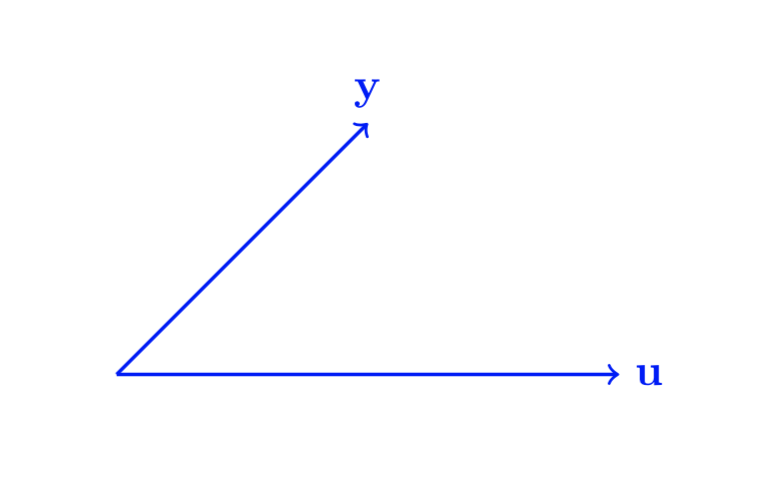

Then we drop a dashed line, starting from the tip of the vector $\textbf y$ and perpendicular (orthogonal) to the vector $\textbf u$.

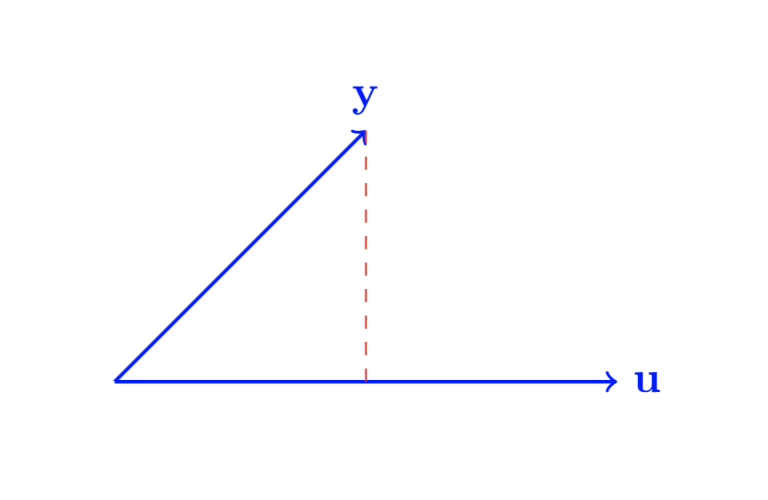

Now, in red, we draw the projection of the vector $\textbf y$ onto the vector $\textbf u$. Note that the projection of $\textbf y$ onto $\textbf u$ is parallel to $\textbf u$, so it is some scalar multiple of $\textbf u$. We symbolize the projection with $\alpha\,\textbf u$.

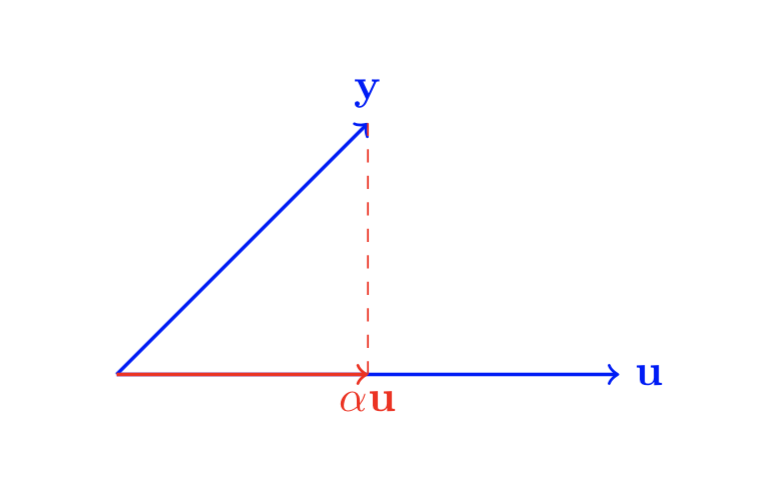

Now we draw a vector starting at the tip of the projected $\alpha\textbf u$ and ending at the tip of the vector $\textbf y$. This is the vector $\textbf y-\alpha\,\textbf u$.

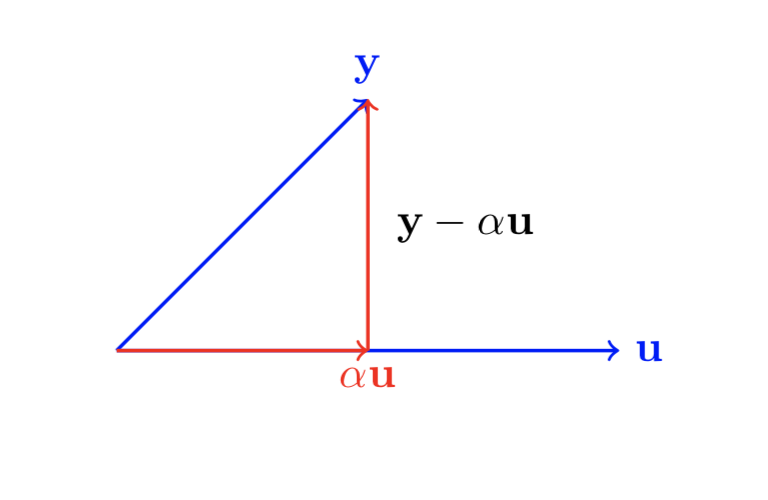

Now, because the vectors $\alpha\,\textbf u$ and $\textbf y -\alpha\,\textbf u$. are orthogonal (perpendicular), their dot product equals zero. Hence, we can write:


$$\begin{array}{rcl}
(\textbf y-\alpha \textbf u)\cdot (\alpha\textbf u)&=&0\\
\alpha[(\textbf y-\alpha\textbf u)\cdot\textbf u]&=&0
\end{array}$$


Note how we used the scalar dot product property which allows us to put the scalar $\alpha$ in front. Now, if $\textbf y$ were perpendicular to $\textbf u$ in our image, then the projection of $\textbf y$ onto the vector $\textbf u$ would be a single point, meaning $\alpha$ would be zero. Now, consider the case where $\alpha\ne 0$, which means we can divide both sides of our last equation by $\alpha$ and continue with:


$$\begin{array}{rcl}
(\textbf y-\alpha\textbf u)\cdot\textbf u&=&0\\
\textbf y\cdot \textbf u-(\alpha\textbf u)\cdot\textbf u&=&0\\
\textbf y\cdot \textbf u-\alpha(\textbf u\cdot\textbf u)&=&0\\
\textbf y\cdot \textbf u&=&\alpha(\textbf u\cdot\textbf u)\\
\end{array}$$


Now, we are projecting $\textbf y$ onto a nonzero vector $\textbf u$, so $\textbf u\cdot\textbf u\ne0$ and we can divide both sides by $\textbf u\cdot\textbf u$, which gives us:


$$\alpha=\frac{\textbf y\cdot\textbf u}{\textbf u\cdot\textbf u}$$


Now, because the orthogonal projection of the vector $\textbf y$ onto the vector $\textbf u$ in our last image is $\alpha\, \textbf u$, this means that we've shown that:


$$\text{proj}_{\textbf u}\,\textbf y=\frac{\textbf y\cdot\textbf u}{\textbf u\cdot\textbf u}\textbf u$$


Now, let's move the vector $\textbf y-\alpha\textbf u$ in our last image so that it starts at the origin.

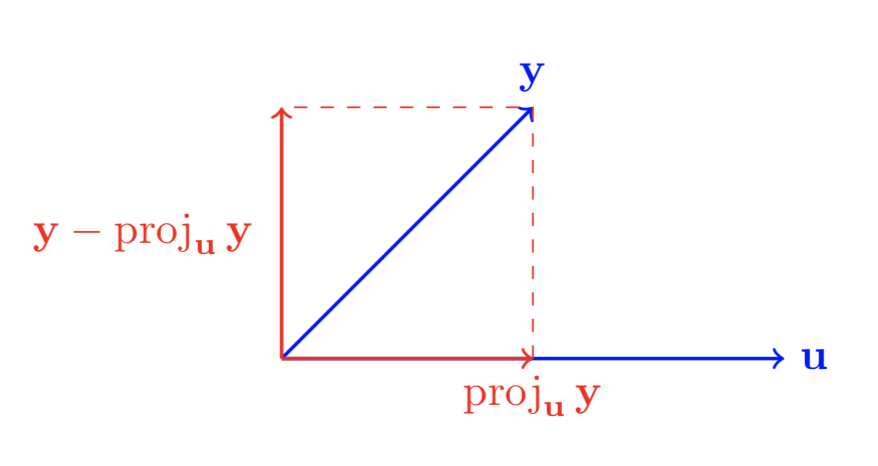

The vector $\textbf y-\text{proj}_{\textbf u}\,\textbf y$ is called the component of $\textbf y$ orthogonal to $\textbf u$. Note that the vector $\textbf y$ is a linear combination of the vectors $\textbf y-\text{proj}_{\textbf u}\,\textbf y$ and $\text{proj}_{\textbf u}\,\textbf y$. Indeed, any vector in $\mathbb R^2$ can be written as a linear combination of $\textbf y-\text{proj}_{\textbf u}\,\textbf y$ and $\text{proj}_{\textbf u}\,\textbf y$, so these two vectors form an orthogonal basis for $\mathbb R^2$.

Let's do some examples to show that this works.

# Example #1

Let


$$\textbf y=\pmatrix{-3\cr 3}\qquad\text{and}\qquad \textbf u=\pmatrix{-5\cr 1}$$


Find the orthogonal projection of $\textbf y$ onto $\textbf u$.

**Solution:** We'll find it easier to use our projection formula if we put our vectors in horizontal form.


$$\begin{array}{rcl}
\text{proj}_{\textbf u}\, \textbf y&=&\frac{\textbf y\cdot\textbf u}{\textbf u\cdot\textbf u}\,\textbf u\\
&=&\frac{(-3,3)\cdot(-5,1)}{(-5,1)\cdot(-5,1)}\pmatrix{-5\cr1}\\
&=&\frac{15+3}{25+1}\pmatrix{-5\cr1}\\
&=&\frac{18}{26}\pmatrix{-5\cr1}\\
&=&\frac{9}{13}\pmatrix{-5\cr1}
\end{array}$$


Therefore, our final answer is:


$$\text{proj}_{\textbf u}\,\textbf y=\pmatrix{-45/13\cr 9/13}$$


We can check our work in Matlab.

y=[-3;3];
u=[-5;1];
proj=dot(y,u)/dot(u,u)*u

proj =    -3.4615
    0.6923


Matlab returns a numerical answer. Is that the same as our hand-calculated answer?

[-45/13;9/13]

ans =    -3.4615
    0.6923


It is. Of course, we could use the format rat command or the symbolic toolbox for an exact answer. We only have to make one element a symbolic element and the symbolic toolbox is called.

proj=dot(y,u)/dot(u,u)*sym(u)

$$proj = \left(\begin{array}{c} -\frac{45}{13}\\ \frac{9}{13} \end{array}\right)$$

Same as our answer. Let's visualize our answer and see if it makes sense. First, we'll draw our vectors $\textbf y=(-3,3)^T$ and $\textbf u=(-5,1)^T$ and prettify our image.

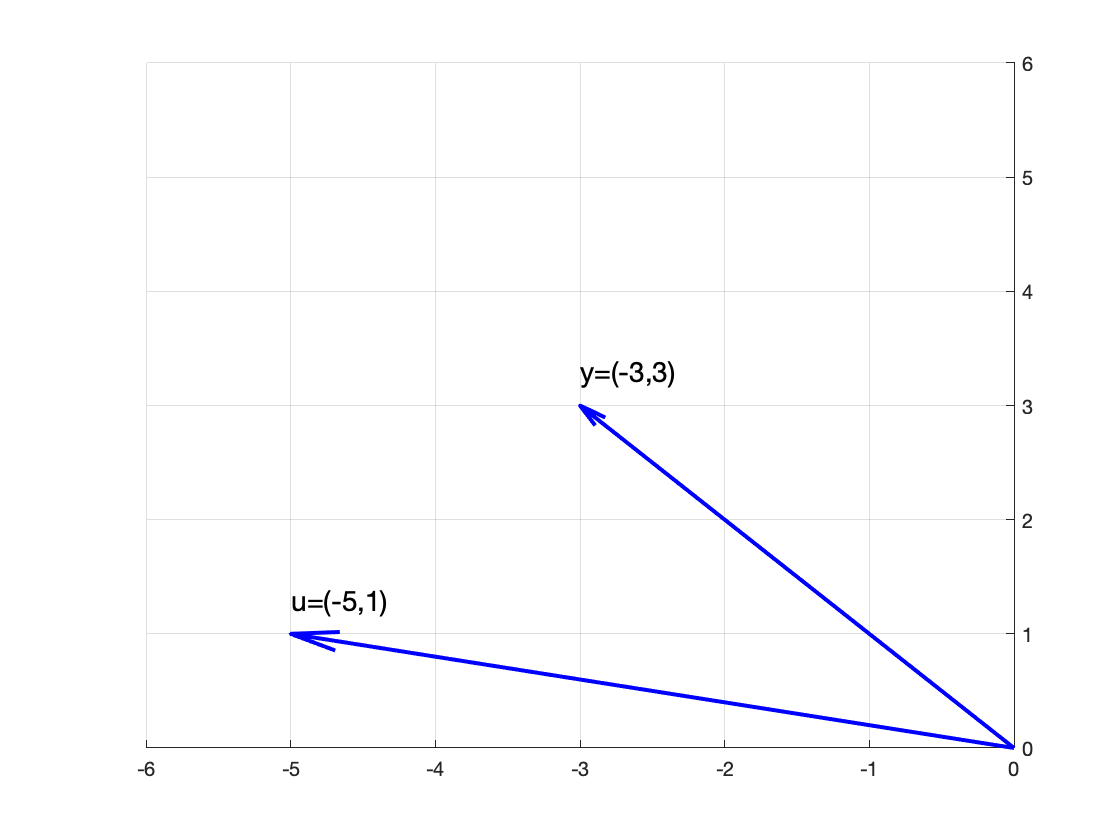

figure
hold on
quiver(0,0,y(1),y(2),0,'LineWidth',2,'Color','b')
quiver(0,0,u(1),u(2),0,'LineWidth',2,'Color','b')
grid on
axis([-6,0,0,6])
xticks(-6:0)
yticks(0:6)
text(-3,3.3,'y=(-3,3)','FontSize',14)
text(-5,1.3,'u=(-5,1)','FontSize',14)
ax=gca;
ax.XAxisLocation='bottom';ax.YAxisLocation='right';
hold off

Now, let's add our answer; that is, $\text{proj}_{\textbf u}\,\textbf y=(-45/13,9/13)^T$.

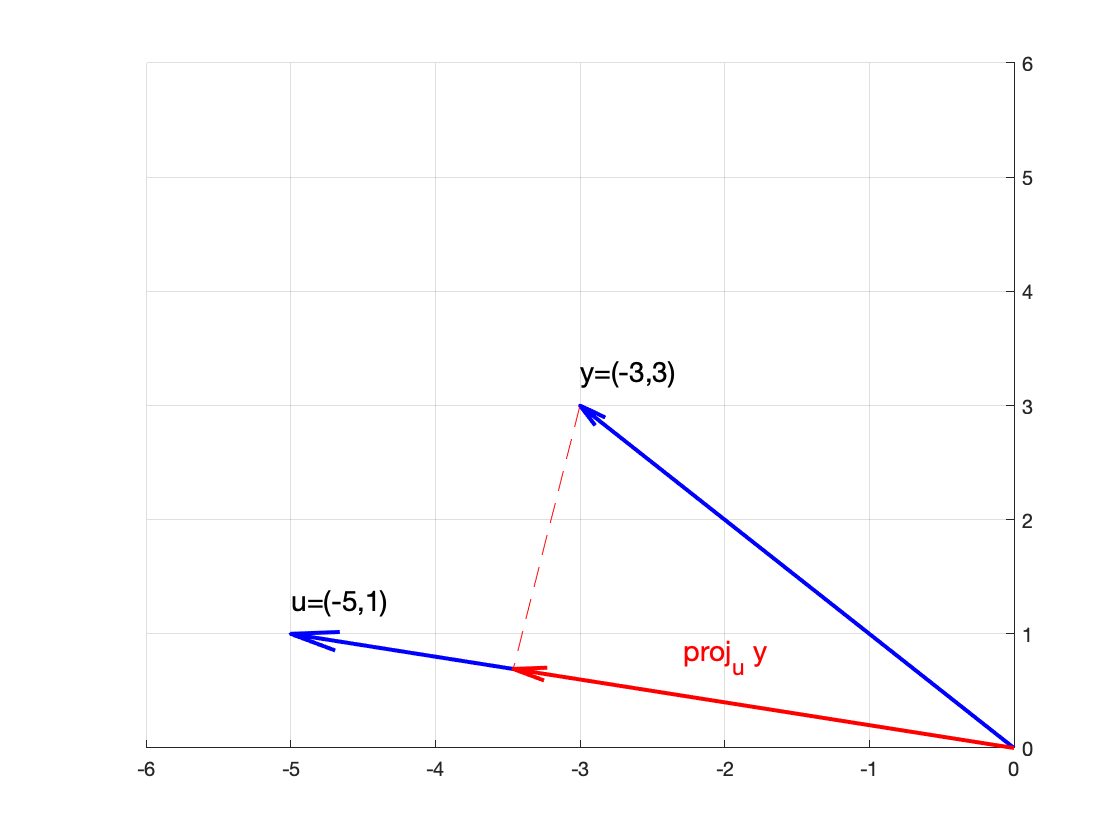

figure
hold on
quiver(0,0,y(1),y(2),0,'LineWidth',2,'Color','b')
quiver(0,0,u(1),u(2),0,'LineWidth',2,'Color','b')
quiver(0,0,proj(1),proj(2),0,'LineWidth',2,'Color','r')
line([proj(1),y(1)],[proj(2),y(2)],'LineStyle','--','Color','r')
grid on
axis([-6,0,0,6])
xticks(-6:0)
yticks(0:6)
text(-3,3.3,'y=(-3,3)','FontSize',14)
text(-5,1.3,'u=(-5,1)','FontSize',14)
text(-2,0.8,'proj_u y','FontSize',14,'HorizontalAlignment','center','Color','r')
ax=gca;
ax.XAxisLocation='bottom';ax.YAxisLocation='right';
hold off

Up above, Matlab returned $\text{proj}_{\textbf u}\,\textbf y\approx(-3.4615,0.6923)^T$. The tip of our red projection vector definitely seems to lie at this point. Great visual evidence that we have done this example correctly.

# Example #2

Let


$$\textbf y=\pmatrix{-1\cr -4}\qquad\text{and}\qquad \textbf u=\pmatrix{2\cr 1}$$


Find the orthogonal projection of $\textbf y$ onto $\textbf u$.

**Solution:** We'll find it easier to use our projection formula if we put our vectors in horizontal form.


$$\begin{array}{rcl}
\text{proj}_{\textbf u}\, \textbf y&=&\frac{\textbf y\cdot\textbf u}{\textbf u\cdot\textbf u}\textbf{ u}\\
&=&\frac{(-1,-4)\cdot(2,1)}{(2,1)\cdot(2,1)}\pmatrix{2\cr1}\\
&=&\frac{-2-4}{4+1}\pmatrix{2\cr1}\\
&=&-\frac{6}{5}\pmatrix{2\cr1}
\end{array}$$


Therefore, our final answer is:


$$\text{proj}_{\textbf u}\,\textbf y=\pmatrix{-12/5\cr -6/5}$$


We can check our work in Matlab.

y=[-1;-4];
u=[2;1];
proj=dot(y,u)/dot(u,u)*u

proj =    -2.4000
   -1.2000


Matlab returns a numerical answer. Is that the same as our hand-calculated answer?

[-12/5;-6/5]

ans =    -2.4000
   -1.2000


It is. Of course, we could use the format rat command or the symbolic toolbox for an exact answer. We only have to make one element a symbolic element and the symbolic toolbox is called.

proj=dot(y,u)/dot(u,u)*sym(u)

$$proj = \left(\begin{array}{c} -\frac{12}{5}\\ -\frac{6}{5} \end{array}\right)$$

Same as our answer. Let's visualize our answer and see if it makes sense. First, we'll draw our vectors $\textbf y=(-1,4)^T$ and $\textbf u=(2,1)^T$ and prettify our image.

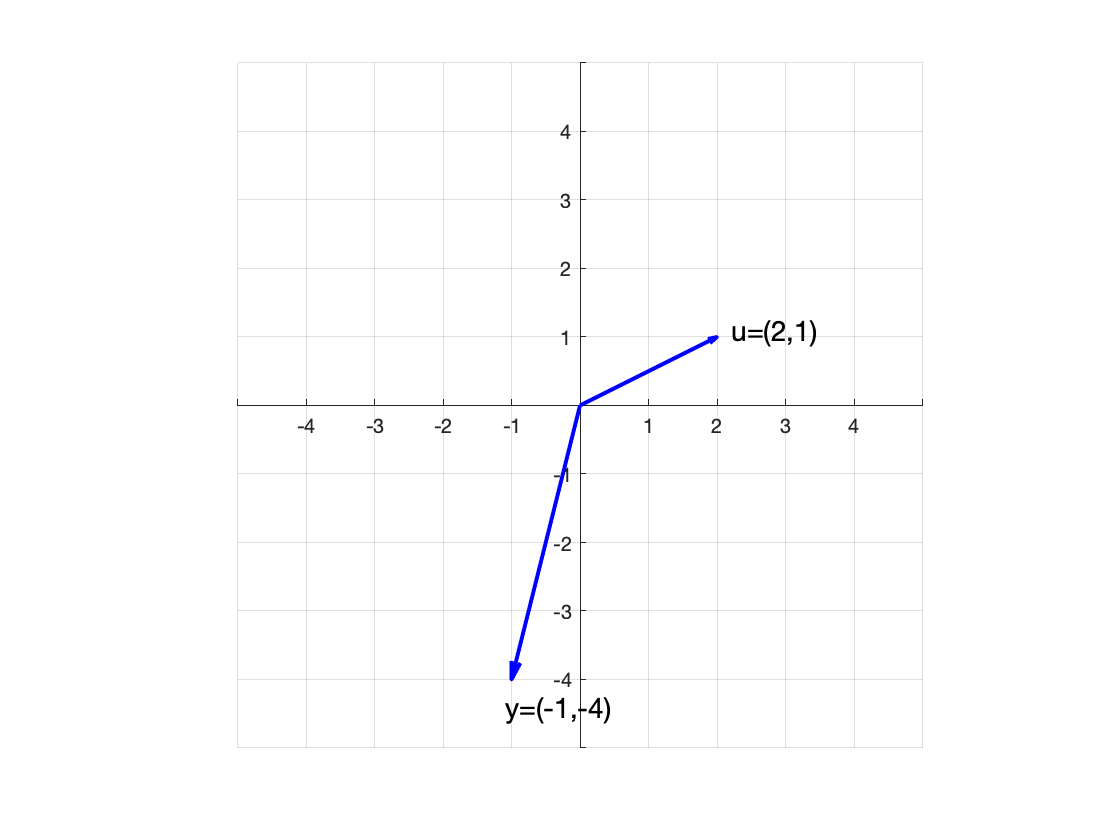

figure
hold on
y=[-1;-4];
u=[2;1];
quiver(0,0,y(1),y(2),0,'LineWidth',2,'Color','b')
quiver(0,0,u(1),u(2),0,'LineWidth',2,'Color','b')
grid on
axis equal
axis([-5,5,-5,5])
xticks(-5:5)
yticks(-5:5)
text(-1.1,-4.4,'y=(-1,-4)','FontSize',14)
text(2.2,1.1,'u=(2,1)','FontSize',14)
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
hold off

This is a bit strange. What does it mean to project the vector $\textbf y$ onto the vector $\textbf u$? One thing that might be helpful is to add the $\text{span}[\textbf u]$ to our image, that is, a line through the origin in the direction of u. Each point on the line must be a scalar multiple of $\textbf u=(2,1)^T$. That is,


$$\begin{array}{rcl}
\pmatrix{x\cr y}=t\pmatrix{2\cr 1}\\
\pmatrix{x\cr y}=\pmatrix{2t\cr t}
\end{array}$$


Now we can add this line to our figure.

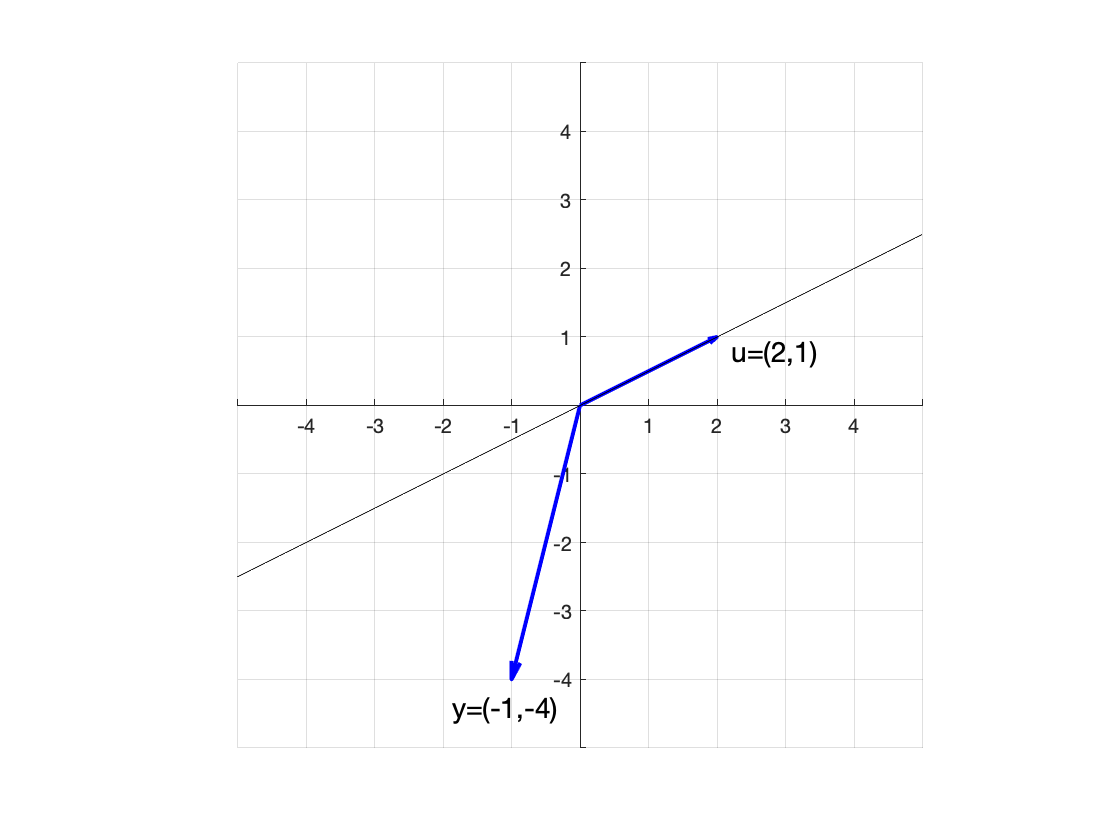

figure
hold on
y=[-1;-4];
u=[2;1];
quiver(0,0,y(1),y(2),0,'LineWidth',2,'Color','b')
quiver(0,0,u(1),u(2),0,'LineWidth',2,'Color','b')
t=linspace(-5/2,5/2);
x=2*t;
y=t;
plot(x,y,'k-')
grid on
axis equal
axis([-5,5,-5,5])
xticks(-5:5)
yticks(-5:5)
text(-1.1,-4.4,'y=(-1,-4)','FontSize',14,'HorizontalAlignment','center')
text(2.2,0.8,'u=(2,1)','FontSize',14)
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
hold off

Aha! We're projecting onto the line spanned by the vector $\textbf u$. Let's add our projection vector $\text{proj}_{\textbf u}\,\textbf y=(-12/5,-6/5)^T$ in red, then a dashed line from our projection vector to the tip of the vector $\textbf y$.

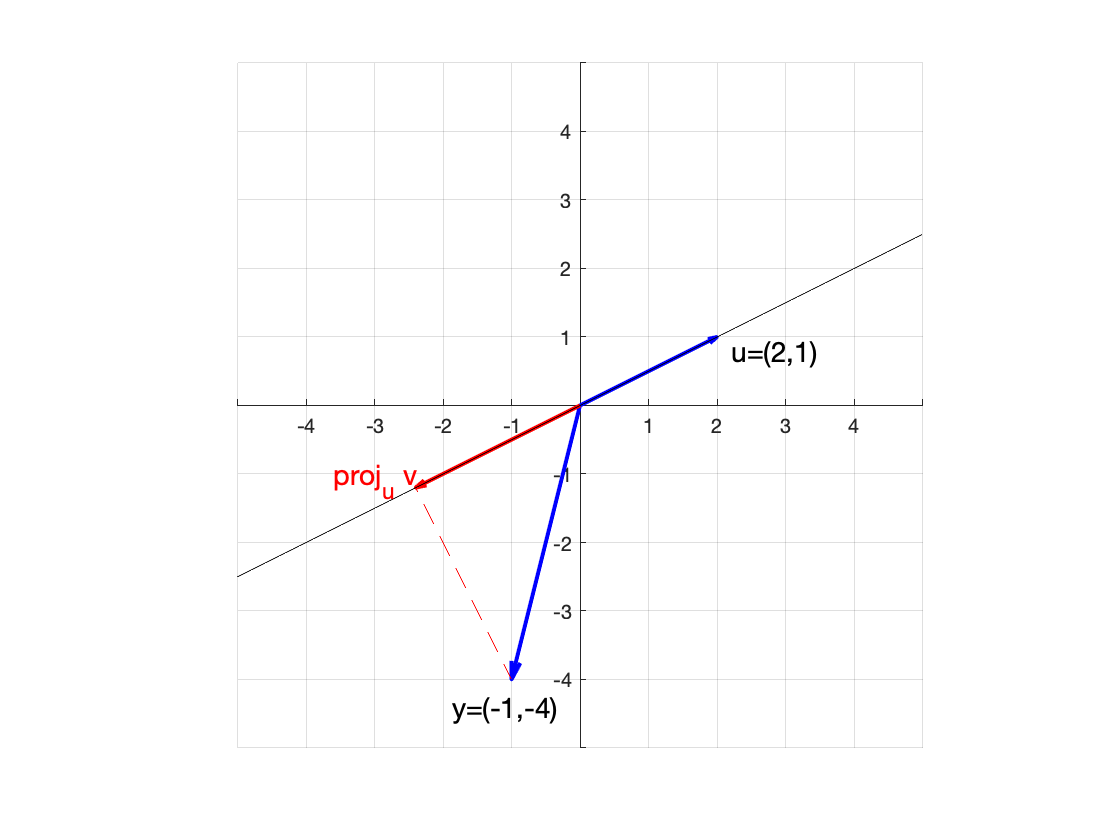

figure
hold on
y=[-1;-4];
u=[2;1];
proj=dot(y,u)/dot(u,u)*u;
quiver(0,0,y(1),y(2),0,'LineWidth',2,'Color','b')
quiver(0,0,u(1),u(2),0,'LineWidth',2,'Color','b')
quiver(0,0,proj(1),proj(2),0,'LineWidth',2,'Color','r')
line([proj(1),y(1)],[proj(2),y(2)],'LineStyle','--','Color','r')
t=linspace(-5/2,5/2);
xx=2*t;
yy=t;
plot(xx,yy,'k-')
grid on
axis equal
axis([-5,5,-5,5])
xticks(-5:5)
yticks(-5:5)
text(-1.1,-4.4,'y=(-1,-4)','FontSize',14,'HorizontalAlignment','center')
text(2.2,0.8,'u=(2,1)','FontSize',14)
text(-3.6,-1.1,'proj_u v','FontSize',14,'Color','r')
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
hold off

Up above, Matlab returned $\text{proj}_{\textbf u}\,\textbf y\approx(-2.4000,-1.2000)^T$. The tip of our red projection vector definitiely seems to lie at this point. Great visual evidence that we have done this example correctly